# Fitting the raw lip signals from 520-700nm

This script demonstrates that we can use two fluorophores (collagen and FAD) and an appropriate blood oxygenation level to fit the raw spectra from the lip over the range from 520 to 700 nm.  

These two fluorophores were adequate:  {'collagen1-smooth','FAD_webfluor'}; 

Notes

- When we use the 450 nm excitation light, there is probably some leakage into the measurement, which starts at 500nm.  So we perform this analysis over the range from 520-700.  If you try with the range from 500-700 the fit is OK, but it misses where the light leaks.

-  We tried adding in deoxygenated blood (commented out, but at the bottom of this notebook).  It did not help.

- The collagen1 had some discontinuities that we smoothed away in d_webfluor.m.  That produced collagen1-smooth. We didn't get rid of the discontinuities entirely, though. 

- We tried many fluorophore files from the literature. The fluorophores in general are described in in **s_oeFluorophoreEmissions.mlx, **the ones we tried are listed below.

See also:

   s_oeDimensionality.mlx

## Programming notes

**Repositories**: isetcam, isetfluorescence and oe_tongue_lip

## Initialize parameters

Different analyses are based on different wavebands.

ieInit;
wave = 520:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:20;
[T,dataDir] = oeDatabaseCreate;

## Select the fluorophores 

Here are notes about fluorophores we tried.

- fluorophoreNamesB = {'CollagenWuQu','NADH_webfluor','FADLin'};

- fluorophoreNamesB = {'CollagenWuQu','FADLin'}; 

- fluorophoreNamesB = {'CollagenWuQu','FADValdez'};

- fluorophoreNamesB = {'CollagenWuQu','FAD_webfluor'};

- fluorophoreNamesB = {'CollagenWuQu','elastin_webfluor','FADValdez'};

- fluorophoreNamesB = {'collagen7','elastin_webfluor','FADValdez'};

- fluorophoreNamesB = {'collagen1','elastin_webfluor','FAD_webfluor','NADH_webfluor'};

- fluorophoreNamesB = {'collagen1'};   % Interesting, but not great

- fluorophoreNamesB = {'elastin_webfluor','FADValdez'}; 

- fluorophoreNamesB = {'elastin_webfluor'};  

- {'collagen1-smooth','FADLin'}; is worse

- {'collagenWuQu','FAD_webfluor'} - WuQu doesn't go out to 700nm.  The fits are a little worse even over 500-600

This is the one that did well.

- fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor'};

## Create fluorophore matrix and read raw lip data

The base fluorophores, without blood, are named in (fluorophoreNamesB).  We load them into a matrix here.

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## 405/415 nm excitation

We read all the lip data for each subject at both 405 nm and 415 nm. The data from different days are from different locations on the lip. 

Then, we estimate the optical density for each subject using oeBloodEstimateOD.  The densities are saved in ods().

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);

rmse = zeros(size(subjects));
odError = zeros(numel(odLevels),numel(subjects));
ods = zeros(numel(subjects),1);    

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    lipData  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,lipData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 13.00
OD across subjects for 405/415nm 10.00
OD across subjects for 405/415nm 8.00
OD across subjects for 405/415nm 8.00


This plot shows the error (odError) as a function of different optical density levels.  For each of the subject separately.

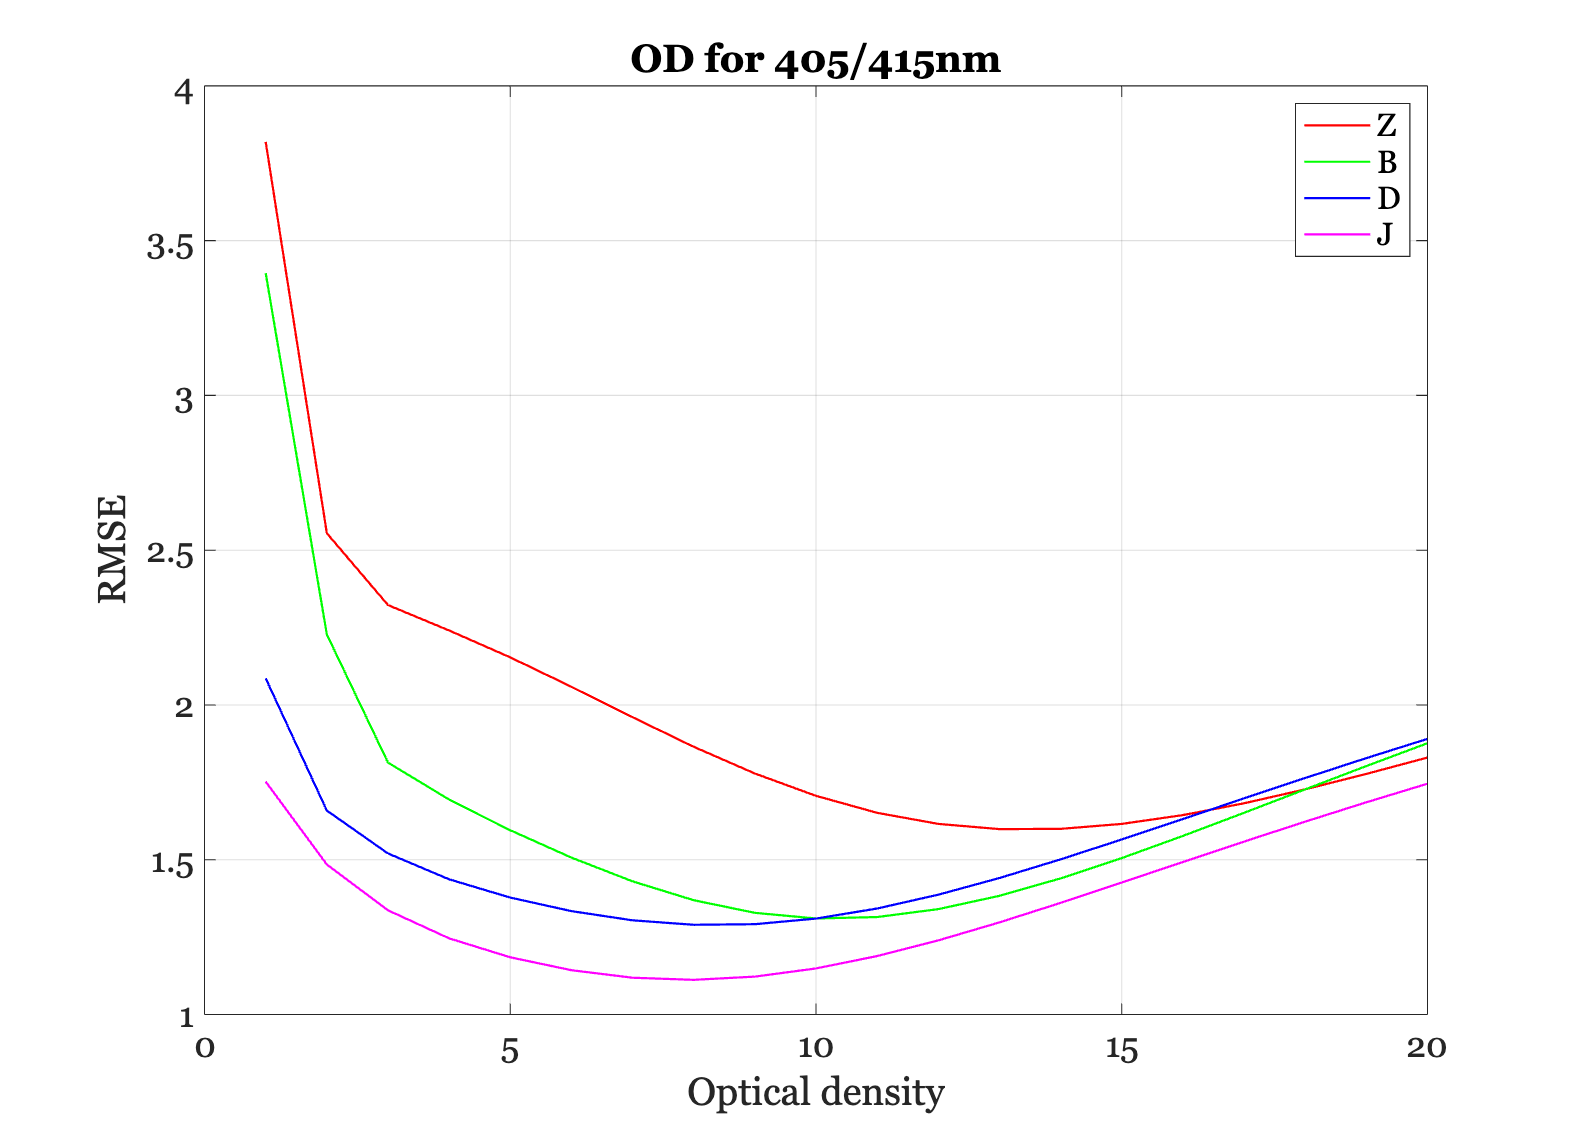

ieFigure;
plot(odLevels,odError);
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Fit the raw lip fluorescence data

We apply the oxygenated blood to the collagen using oeApplyBlood to create a new fluorophores basis.  We then fit the raw lip data using non-negative least squares for the new basis.

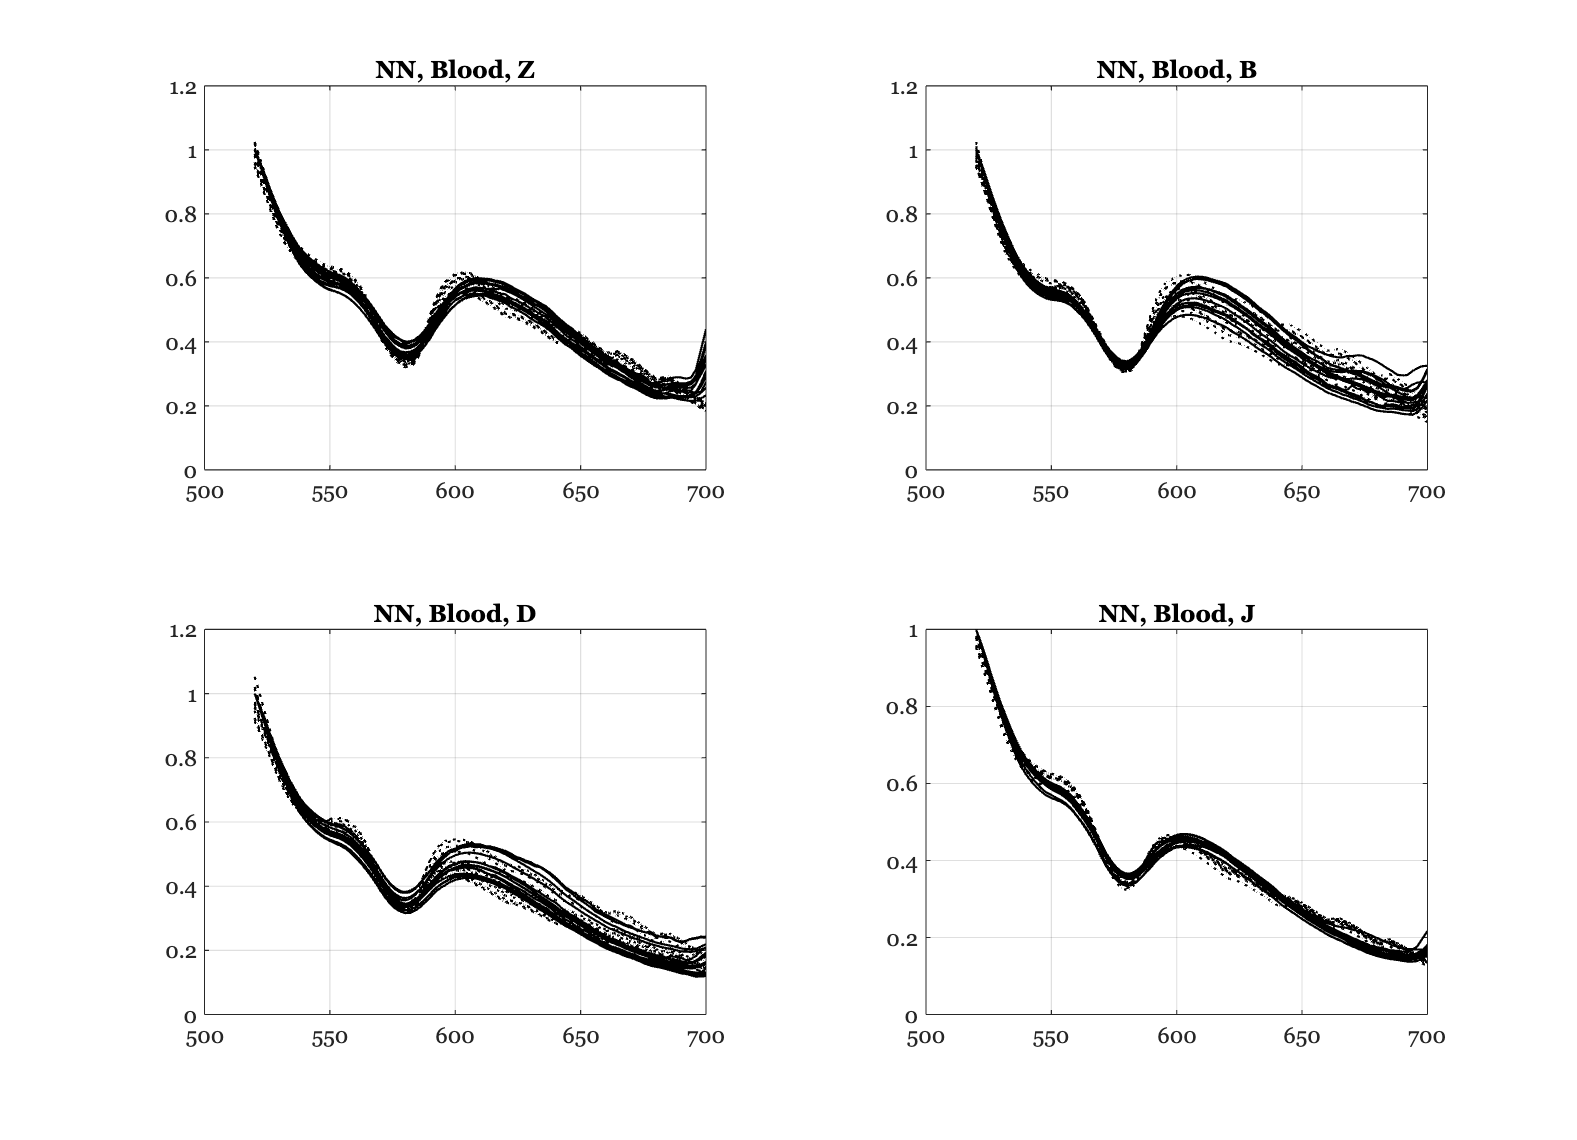

Subject Z
   16.1386   17.4202   16.5207   17.0280   15.9700   17.7701   18.3058   18.0756   17.8743   16.4013   16.5310   17.5657   18.3849   18.0901
    0.6475    0.6630    0.6421    0.6656    0.6615    0.6750    0.6780    0.6506    0.6554    0.6567    0.6551    0.6749    0.6803    0.6890

Subject B
   17.0864   14.5901   15.7049   12.9360   13.8576   18.0888   18.1724   14.3350   14.5058   16.3644   16.7463   18.9731   16.7108
    0.5515    0.5715    0.5486    0.6150    0.5935    0.5386    0.5410    0.5976    0.5961    0.5514    0.5510    0.5331    0.5478

Subject D
   10.9828   10.8984   11.2898   15.7147   15.9943   11.0855   11.6440   13.0339   11.9227   15.2802   14.2980   12.3095   12.8035   12.3164
    0.5717    0.5669    0.5656    0.5479    0.5402    0.5941    0.5859    0.5579    0.5803    0.5309    0.5578    0.5753    0.5616    0.5637

Subject J
   12.0238   11.6084   12.0393   11.3497   11.3458   10.8047   10.7783   11.5240   11.2675   11.8182   11.8638   11.6363   11.7379 

ieFigure;
tiledlayout(2,2);

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);

    lipData = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);

    % Set the blood density for this subject
    oxyblood.opticalDensity = ods(ii);

    % Create the new fluorophore basis and update the names
    [fluorophores,fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);

    % Solve for the non-negative weights
    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));
    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end

    % Find the error
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);
    
    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

These are the approximate levels of the basis functions used to fit the data.  Note that there is some non-smooth characteristic of the collagen1-smooth.  Maybe we should smooth it some more. 

We apply the weights from the last subject here to show the general scaling of the fluorophores

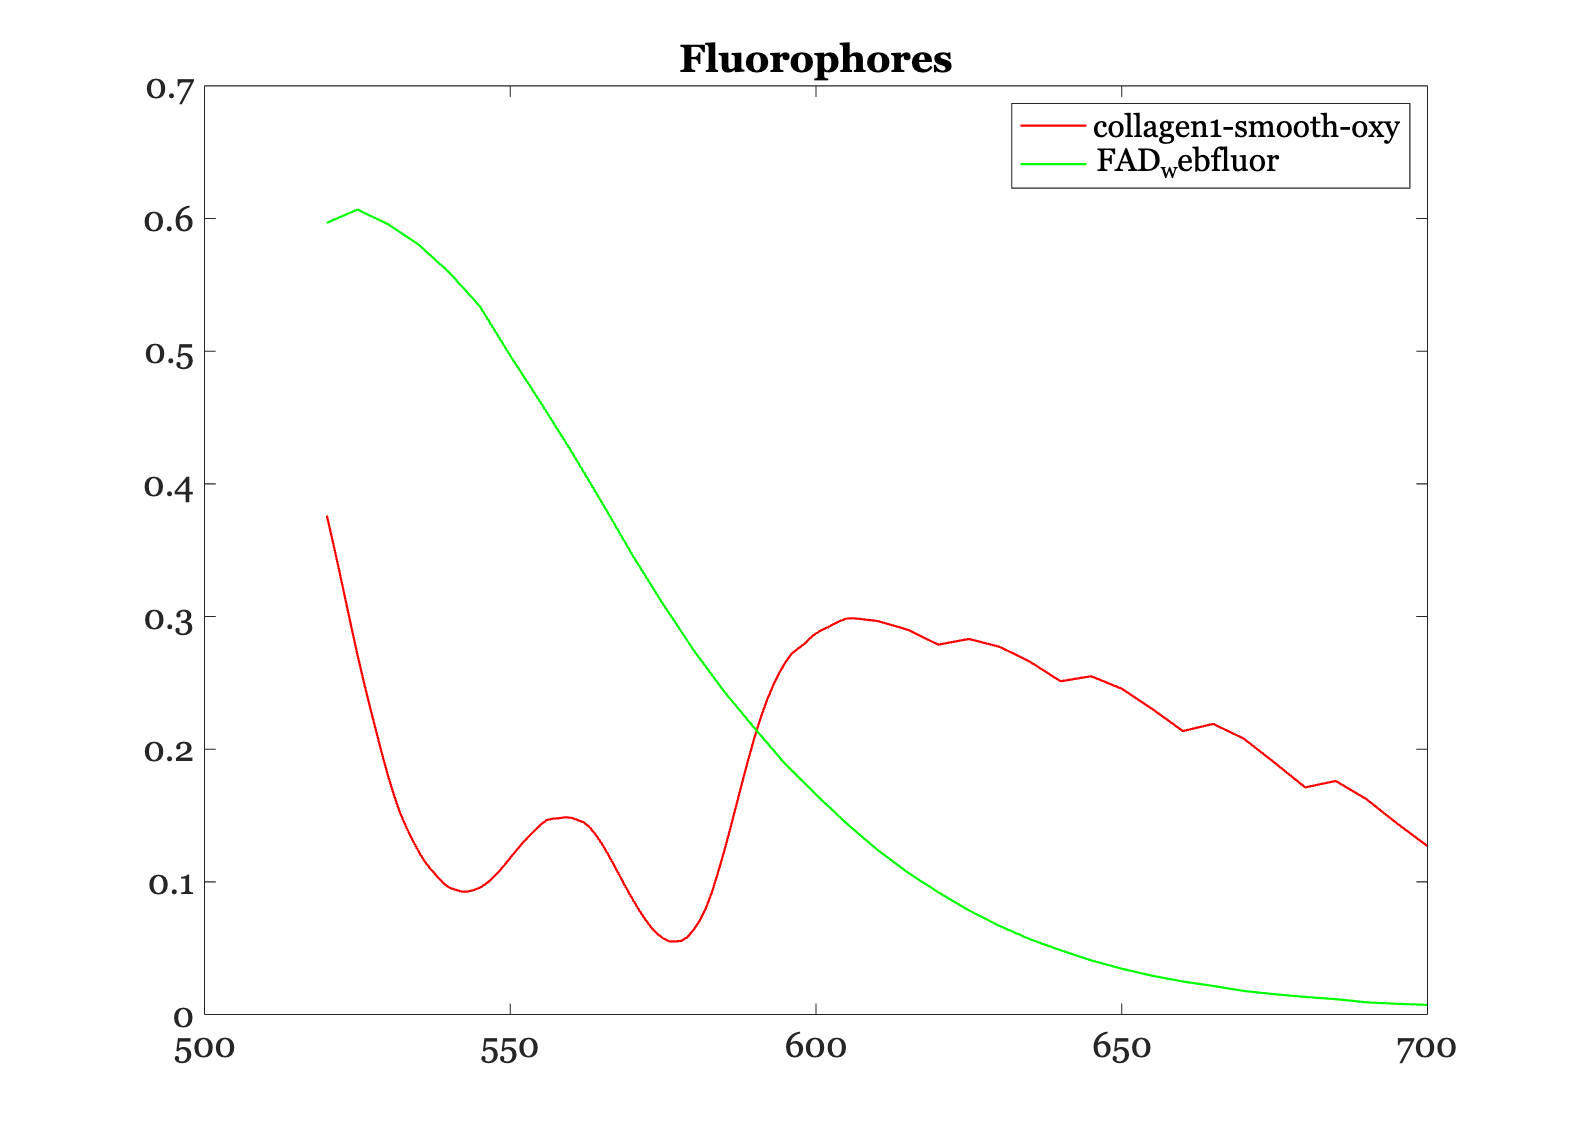

ieFigure; 
plot(wave,fluorophores*diag(mean(wgtsNN,2)));
title('Fluorophores');
legend(fluorophoreNames);

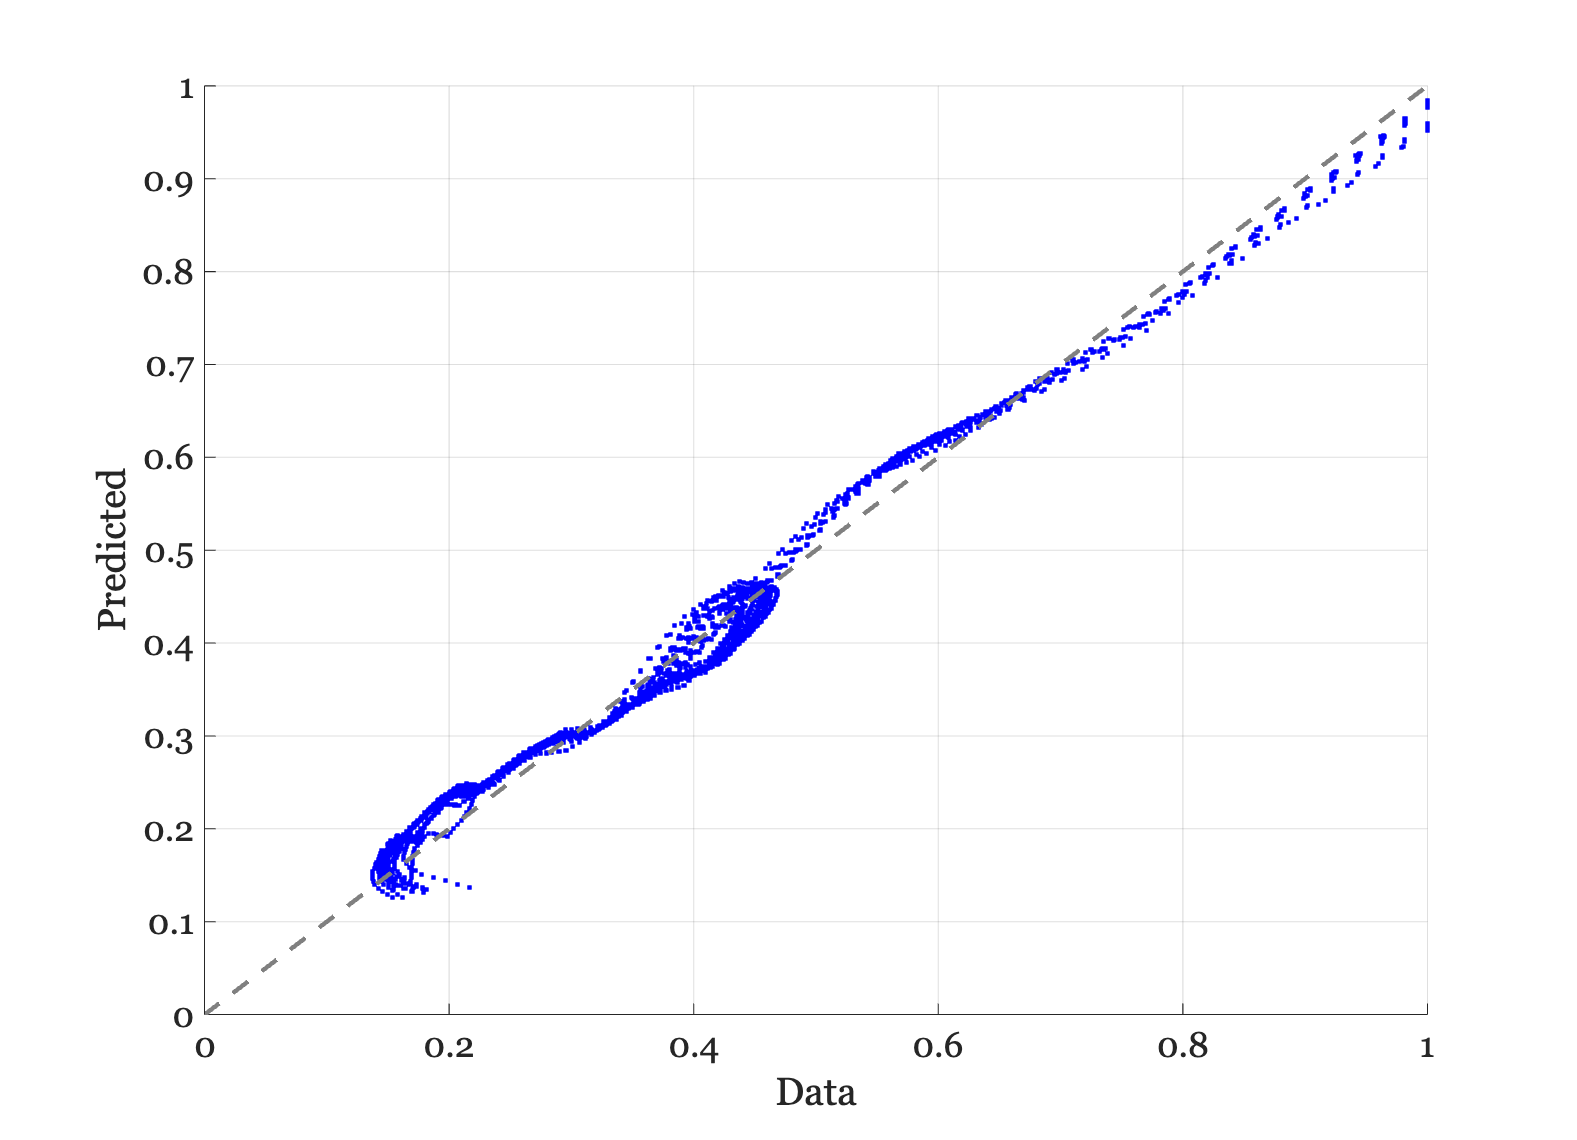

% Scatter plot of observed and predicted.
ieFigure;
tmp = fluorophores*wgtsNN;
scatter(lipData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');

## Repeat the analysis for the 450 nm excitation light

The blood oxygen density estimates for the 450 nm excitation light OD seems to be a bit different. We explain this by saying this wavelength penetrates a bit deeper into the tissue and thus encounters more blood.    

This also made us wonder whether we need some deoxygenated blood included.  We tried that, but it wasn't helpful.

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','lip',...
        'e wave',450);
    lipData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,lipData,wave,odLevels);
end
fprintf('OD across subjects for 450nm %.2f\n',ods);

OD across subjects for 450nm 17.00
OD across subjects for 450nm 17.00
OD across subjects for 450nm 11.00
OD across subjects for 450nm 12.00


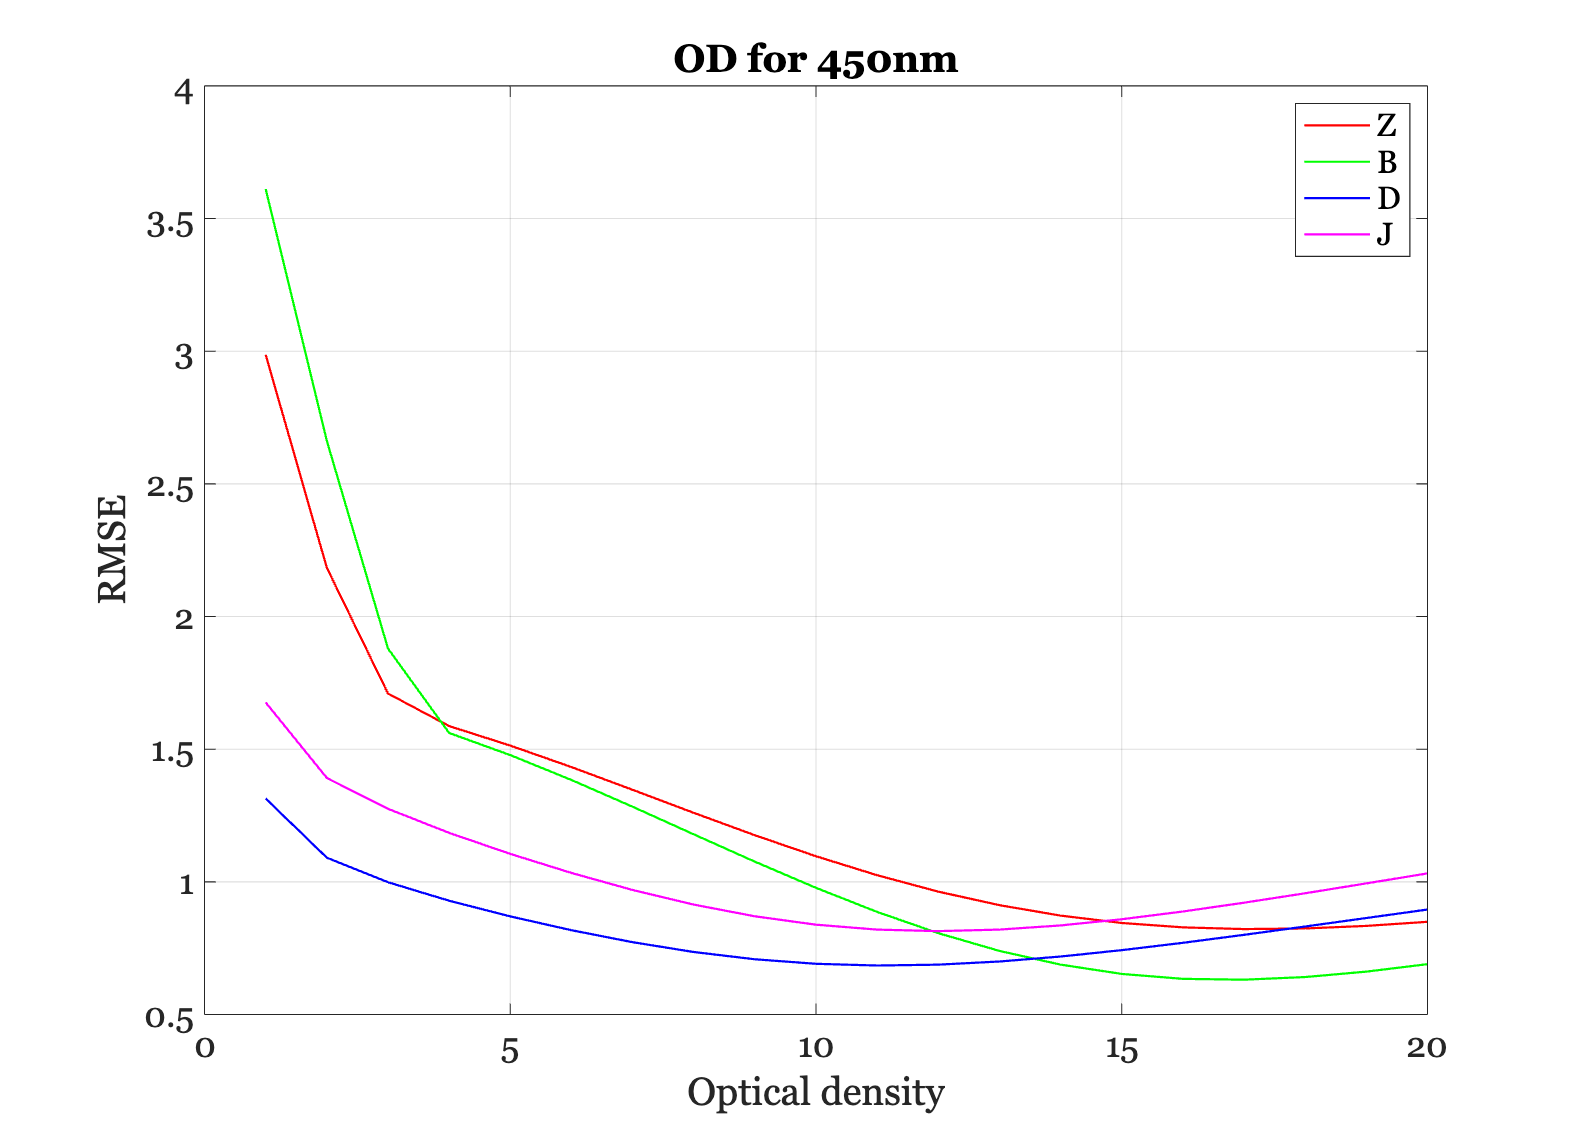

ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');  

## 450 nm excitation light

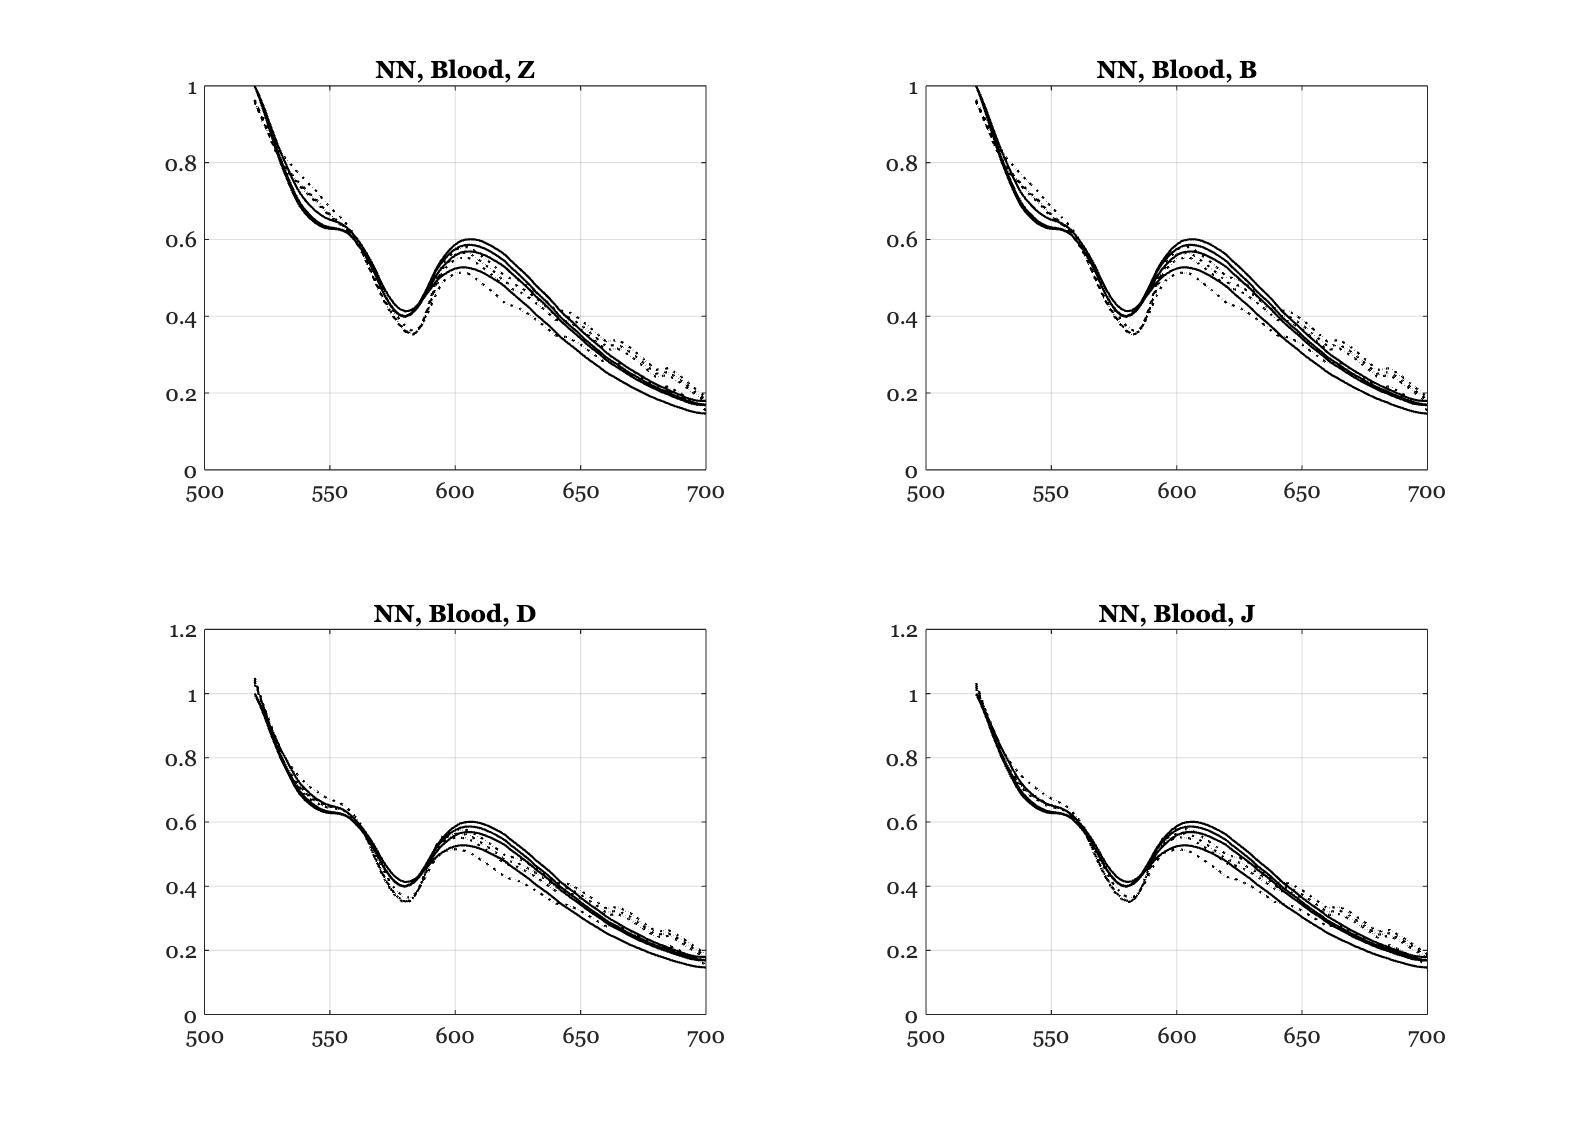

Subject Z
   15.3515   15.9051   13.3636   16.5774
    0.7775    0.7742    0.8051    0.7688

Subject B
   15.3515   15.9051   13.3636   16.5774
    0.7775    0.7742    0.8051    0.7688

Subject D
   15.2565   15.8065   13.2901   16.4669
    0.6857    0.6790    0.7250    0.6697

Subject J
   15.2556   15.8059   13.2877   16.4676
    0.7077    0.7019    0.7442    0.6936



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)

    % Set the density
    oxyblood.opticalDensity = ods(ii);

    % Apply the blood to the collagen
    [fluorophores, fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    
    % Solve for the non-negative weights
    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));
    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end

    % Calculate the error
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);

    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

disp(fluorophoreNames'); 

    {'collagen1-smooth-oxy'}
    {'FAD_webfluor'        }



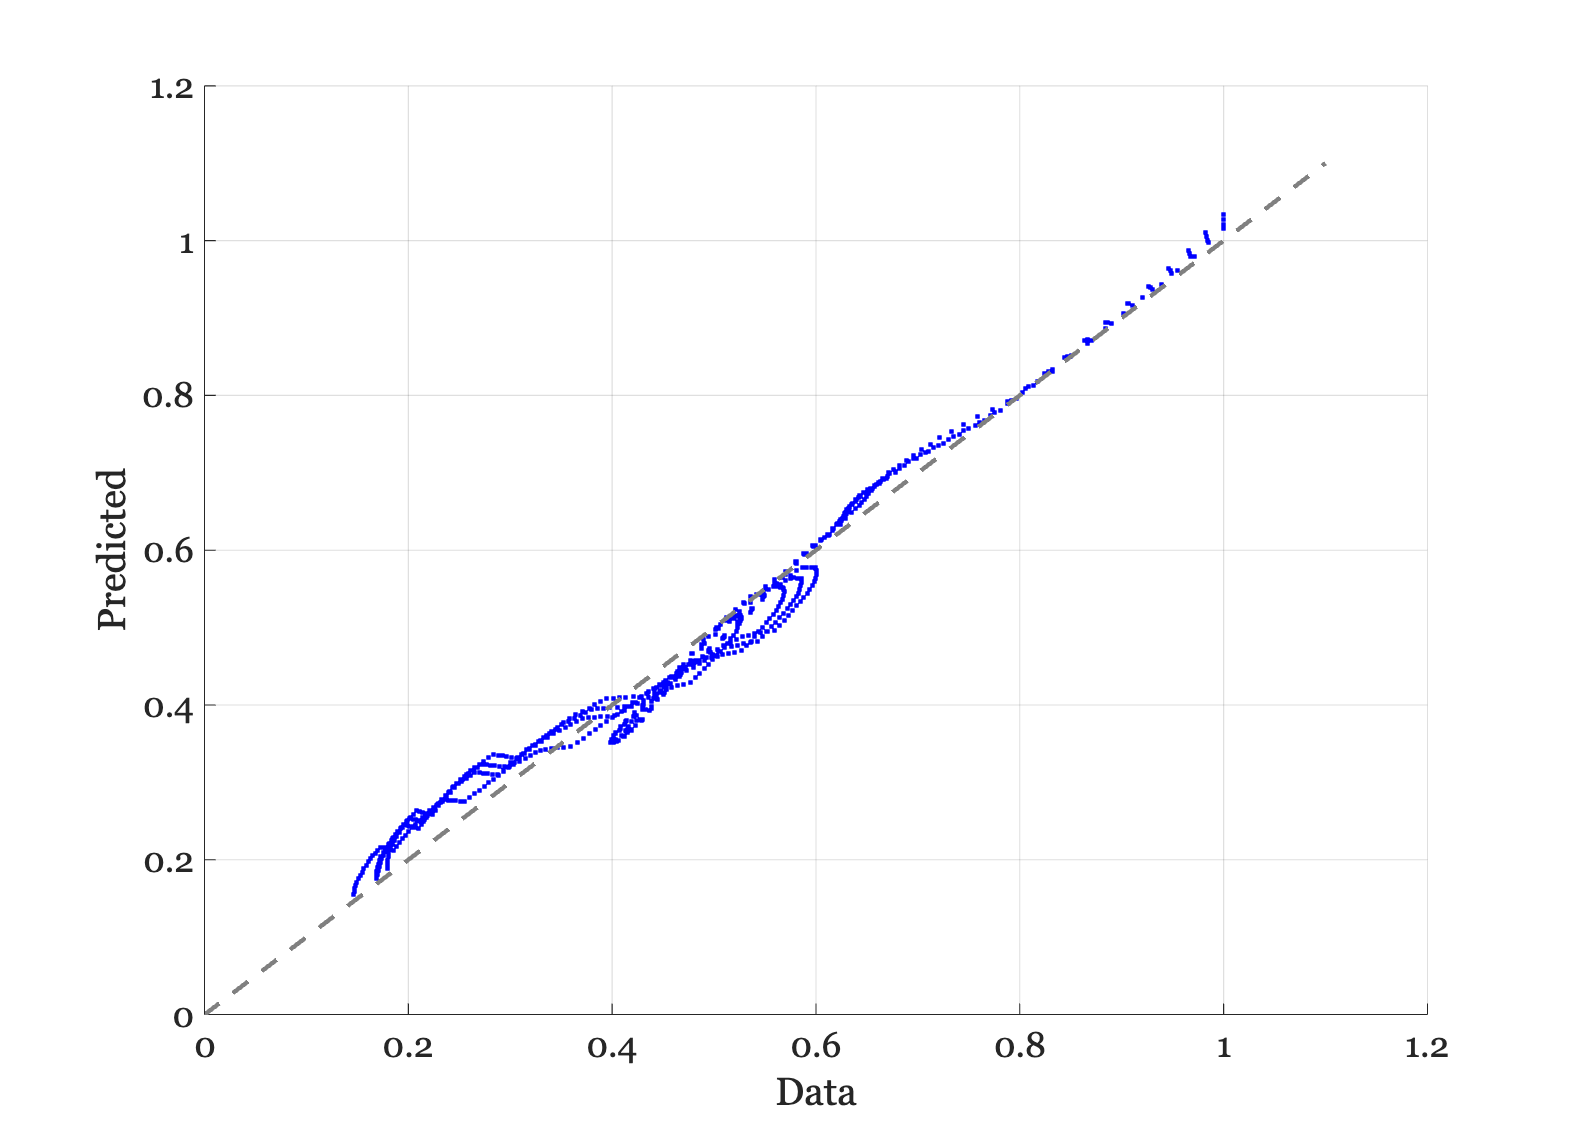


ieFigure;
tmp = fluorophores*wgtsNN;
scatter(lipData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');

## Once more with deoxy

There is no real value add in this case for putting in a lot or a little deoxy.  We tried OD of 5, 30, and 60.  We could see the weights changing but not the RMSE.  Two of the subjects don't use the deoxy at all in any case.

%{
deoxyblood = medium('deoxy_molarExtinctionCoefficient.mat','wave',wave);
deoxyblood.opticalDensity = 8;
%{
ieFigure;
plot(wave,deoxyblood.transmittance,'b-',wave,oxyblood.transmittance,'r-');
%}

ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,...
        oxyblood, ...
        'deoxy',deoxyblood);

    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);

    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end
disp(fluorophoreNames'); 
ieFigure;
tmp = fluorophores*wgtsNN;
scatter(lipData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');
%}
